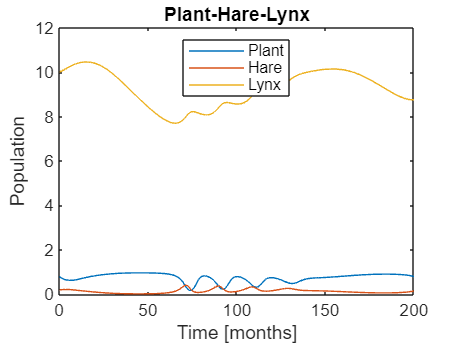

t0 = 0;                 	% start time of simulation [in months]
tfinal = 200;                % end time of simulation [in months]
y0= [0.8 0.2 10];               % initial state i.e. number of plants, hares and lynxs at t=0
tspan = [t0 tfinal];        % time span defined by the start and end times of the simulation [in months]
a1 = 5;               % predation success rate parameter ("how likely that the hare dies if it meets a lynx")
a2= 0.1;              % lynx population increase rate due to predation on tuna ("how much food a linx gets out of eating a hare")
b1= 3;
b2= 2;
d1= 0.4;
d2=0.011;

[t,y] = ode23(@(t,y) plants_hare_lynx_(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);

% plotting the population over time
figure("Name",'hare-lynx');
plot(t,y)
title('Plant-Hare-Lynx');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','North');

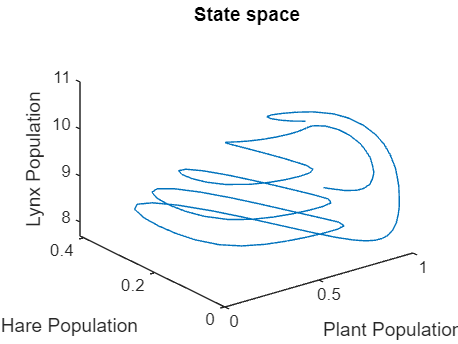

figure("Name",'State space')
plot3(y(:,1),y(:,2),y(:,3))
title('State space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')